%Project 4 - Drone Battery Flight Time
%Benjamin Oakes - Computer Applications

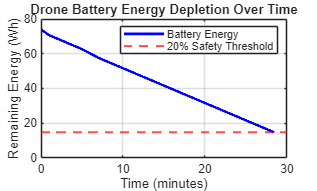


clear; clc; close all;

BATT_CAPACITY_AH = 5.0;     % Capacity in Ampere-hours (5000 mAh)
BATT_VOLTAGE_V = 14.8;      % Nominal voltage (4S LiPo)
BATT_SAFETY_MARGIN = 0.20;  % Land at 20% capacity

% Calculate initial energy
initial_energy_wh = BATT_CAPACITY_AH * BATT_VOLTAGE_V;
initial_energy_joules = initial_energy_wh * 3600; 

% Power Consumption for Flight Modes (Watts)
P_ASCENT = 200; 
P_HOVER = 150;  
P_CRUISE = 120; 

% Simulation Parameters
dt = 1; % Time step (seconds)
max_sim_time_s = 3600; 
time_vector = 0:dt:max_sim_time_s;
num_steps = length(time_vector);

% INITIALIZE SIMULATION VARIABLES
energy_vector = zeros(1, num_steps);
energy_vector(1) = initial_energy_joules;
end_of_flight_energy = initial_energy_joules * BATT_SAFETY_MARGIN;
total_flight_time_s = 0;

%% 3. RUN THE SIMULATION
for i = 2:num_steps
    current_time_s = time_vector(i);
    
    % Define Flight Profile
    if current_time_s <= 60          % 0-1 min: Ascent
        current_power = P_ASCENT;
    elseif current_time_s <= 300     % 1-5 min: Cruise
        current_power = P_CRUISE;
    elseif current_time_s <= 420     % 5-7 min: Hover
        current_power = P_HOVER;
    else                             % 7+ min: Cruise
        current_power = P_CRUISE;
    end
    
    energy_vector(i) = energy_vector(i-1) - (current_power * dt);
    
    if energy_vector(i) <= end_of_flight_energy
        total_flight_time_s = current_time_s;
        time_vector = time_vector(1:i);
        energy_vector = energy_vector(1:i);
        break;
    end
end

figure('Color', 'w');
plot(time_vector / 60, energy_vector / 3600, 'b-', 'LineWidth', 2);
hold on;
yline(end_of_flight_energy / 3600, 'r--', 'LineWidth', 1.5);
title('Drone Battery Energy Depletion Over Time');
xlabel('Time (minutes)'); ylabel('Remaining Energy (Wh)');
legend('Battery Energy', '20% Safety Threshold');
grid on;


fprintf('Total Achievable Flight Time: %.2f minutes\n', total_flight_time_s / 60);

Total Achievable Flight Time: 28.43 minutes
